# 2. naloga

Rešitev enačbe 


$$-(p(x)y')' + g(x)y = r(x), \quad x \in (a,b),$$


pri robnih pogojih


$$y(a) = \alpha, \quad y(b) = \beta.$$


## Pristop

Funkcijo bomo izračunali na $J + 1$ ekvidistantnih točkah $x_j = a + jh = a + j\frac{b - a}{J+1}$. Vrednosti $y(x_j)$ označimo z $y_j$, ustrezati morajo enačbam

$ h^2 r(x_j)  = - p( x_{j-1/2} ) y_{j-1} + \left[ p( x_{j-1/2} + p( x_{j+1/2}) + h^2 q(x_j) \right] y_j  - p( x_{j+1/2}) y_{j+1}$,

za $j=1,\dots,J
$.

Tako lahko zapišemo sistem enačb $A \underline{y} = \underline{b}$, kjer je 

- $b_1 = h^2 r(x_1) + p(x_{1/2}) \alpha
$,

- $b_k = h^2 r(x_k)$ za $k=2,\dots,J-1$,

- $b_J = h^2 r(x_J) + p(x_{J+1/2}) \beta$,

- $A_{j,j} =  p( x_{j-1/2} ) + p( x_{j+1/2}) + h^2 q(x_j)$ za $j=1,\dots,J$,

- $A_{j,j-1}  = - p(x_{j-1/2})$ za $j=2,\dots,J$ in

- $A_{j,j+1}  = - p(x_{j+1/2})$ za $j=1,\dots,J-1$.

Oglejmo si primer iz domače naloge, kjer so $p(x) = 1 + x^2$, $q(x) = x^2$, $r(x) = -1$, $[a,b] = [0,1]$ pri različnih začetnih pogojih in za različne vrednosti $J$. Za začetek naj bosta obe robni vrednosti enaki 0, oglejmo si rezultate za različne vrednosti $J$

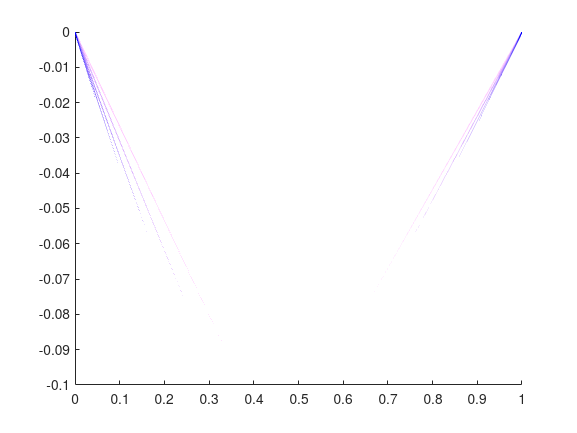

p = @(x) 1 + x^2;
q = @(x) x^2;
r = @(x) -1;
a = 0;
b = 1;

figure(1);
clf;
hold on;

[~,PRIMER_ENA_TEST] = resiRobniProblem1D(p,q,r,a,b,10,0,0);

% Create a colormap from pale blue to blue
cmap = [linspace(1, 0, 8)', linspace(0.8, 0, 8)', ones(8, 1)];
J = [2 3 5 9 20 42 77 100];

for i = 1:8
    [x,y] = resiRobniProblem1D(p,q,r,a,b,J(i),0,0);
    
    % Use the colormap to set the color of the plot
    plot(x, y, 'Color', cmap(i, :), 'LineWidth', 1)
end

colormap(cmap);



p_trig = @(x) -1;
q_trig = @(x) 1;
r_trig = @(x) 0;
a_trig = 0;
b_trig = 2 * pi;
alpha_trig = 1;
beta_trig = 1;

figure(2);
clf;
hold on;

[~, PRIMER_SIN_TEST] = resiRobniProblem1D(p_trig,q_trig,r_trig,a_trig,b_trig,10,alpha_trig,beta_trig);

% Create a colormap from pale blue to blue
cmap = [linspace(1, 0, 8)', linspace(0.8, 0, 8)', ones(8, 1)];
J = [2 3 5 9 20 42 77 100];

for i = 1:8
    [x,y] = resiRobniProblem1D(p_trig,q_trig,r_trig,a_trig,b_trig,J(i),alpha_trig,beta_trig);
    
    % Use the colormap to set the color of the plot
    plot(x, y, 'Color', cmap(i, :), 'LineWidth', 1)
end

colormap(cmap);

### Napake

Oglejmo največjo absolutno napako glede na število notranjih točk. Obravnavali bomo primere, ko je $J = 2,4,7,14,22,32,45,70,100$.

**Prvi primer**

$p(x) = -1$, $q(x) = 1
$, $r(x) = 0$, $a = 0
$, $b = 2 \pi$, $\alpha = 1$,$\beta = 1$. Analitčna rešitev tega problema je $y(x) = \sin (x)$.

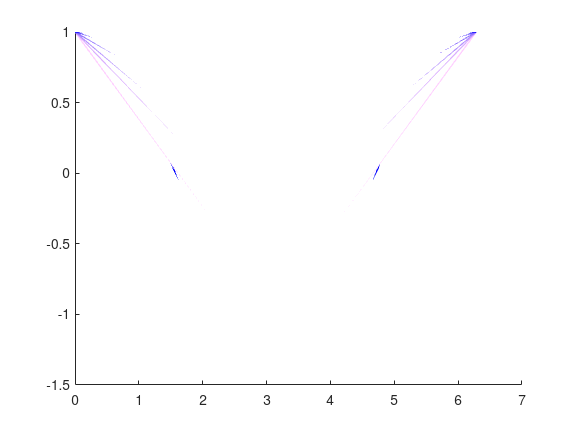

J_napake = [2 4 7 14 22 32 45 70 100];

% primer 1
a1 = 0;
b1 = 2*pi;
alpha1 = 1;
beta1 = 1;
p1 = @(x) -1;
q1 = @(x) 1;
r1 = @(x) 0;
analiticna1 = @(x) (alpha1*cos(b1) - beta1*cos(a1))/sin(a1-b1)*sin(x) - (alpha1*sin(b1) - beta1*sin(a1))/sin(a1-b1)*cos(x);
napake1 = zeros(1,9);
napake1_rel = zeros(1,9);

tiledlayout(2,1)

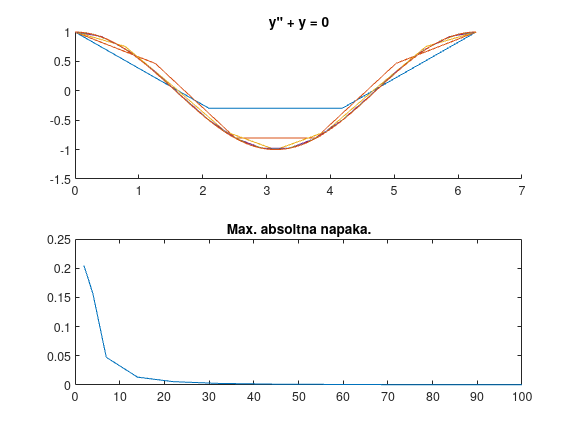

nexttile
hold on;
for J_i = 1:9
    [x1, y1] = resiRobniProblem1D(p1,q1,r1,a1,b1,J_napake(J_i),alpha1,beta1);
    plot(x1,y1)
    napake1(1,J_i) = max( abs(y1' - analiticna1(x1)) );
end
hold off;
title("y'' + y = 0")

nexttile
plot(J_napake,napake1)
title("Max. absoltna napaka.")


clf;

**Drugi primer**

$p(x) = -1$, $q(x) = 1
$, $r(x) = 0$, $a = 0
$, $b = 30
$, $\alpha = 6$,$\beta = -23$. Analitčna rešitev tega problema je $y(x) = A \sin (x) + B \cos (x) + \exp(x) / 2$.

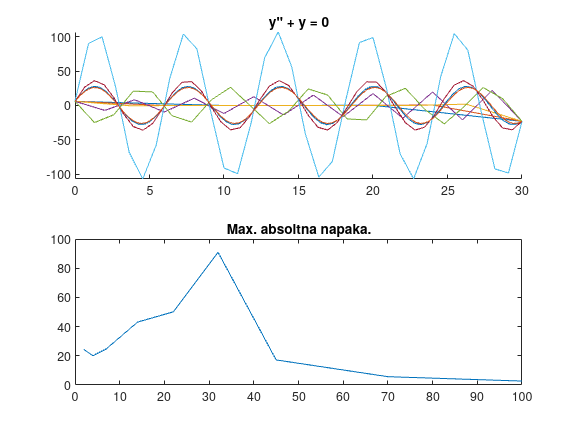

% primer 2
a2 = 0;
b2 = 30;
alpha2 = 6;
beta2 = -23;
p2 = @(x) -1;
q2 = @(x) 1;
r2 = @(x) 0;
analiticna2 = @(x) (alpha2*cos(b2) - beta2*cos(a2))/sin(a2-b2)*sin(x) - (alpha2*sin(b2) - beta2*sin(a2))/sin(a2-b2)*cos(x);
napake2 = zeros(1,9);

[~,PRIMER_TRI_TEST] = resiRobniProblem1D(p2,q2,r2,a2,b2,10,alpha2,beta2);

tiledlayout(2,1)
nexttile
hold on;
for J_i = 1:9
    [x2, y2] = resiRobniProblem1D(p2,q2,r2,a2,b2,J_napake(J_i),alpha2,beta2);
    plot(x2,y2)
    napake2(1,J_i) = max( abs(y2' - analiticna2(x2)) );
end
hold off;
title("y'' + y = 0")

nexttile
plot(J_napake,napake2)
title("Max. absoltna napaka.")


clf;

**Tretji primer**

$p(x) = -1$, $q(x) = 1
$, $r(x) = \exp(x)$, $a = 0
$, $b = 7
$, $\alpha = -1
$,$\beta = 2$. Analitčna rešitev tega problema je $y(x) = A \sin (x) + B \cos (x) + \exp(x) / 2$.

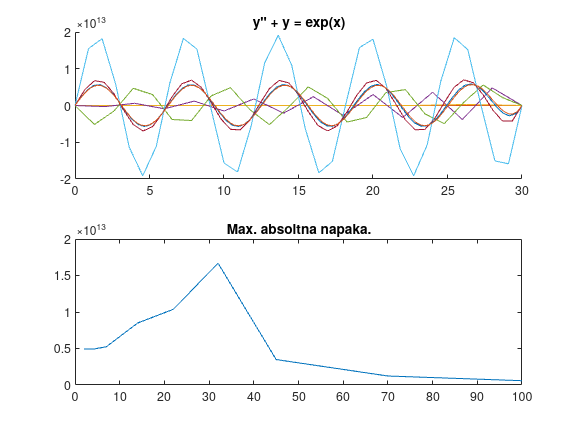

% primer 3
a3 = 0;
b3 = 30;
alpha3 = -12;
beta3 = 8;
p3 = @(x) -1;
q3 = @(x) 1;
r3 = @(x) exp(x);
analiticna3 = @(x) ((alpha3-(exp(a3))/2)*cos(b3) - (beta3 -(exp(b3))/2)*cos(a3))/sin(a3-b3)*sin(x) - ((alpha3-(exp(a3))/2)*sin(b3) - (beta3-(exp(b3))/2)*sin(a3))/sin(a3-b3)*cos(x) + exp(x)/2;
napake3 = zeros(1,9);
napake3_rel = zeros(1,9);

[~,PRIMER_STIRI_TEST]= resiRobniProblem1D(p3,q3,r3,a3,b3,10,alpha3,beta3);

tiledlayout(2,1)
nexttile
hold on;
for J_i = 1:9
    [x3, y3] = resiRobniProblem1D(p3,q3,r3,a3,b3,J_napake(J_i),alpha3,beta3);
    plot(x3,y3)
    napake3(1,J_i) = max( abs(y3' - analiticna3(x3)) );
end
hold off;
title("y'' + y = exp(x)")

nexttile
plot(J_napake,napake3)
title("Max. absoltna napaka.")

### Časovna zahtevnost

Oglejmo si časovno zahtevnost glede na velikost $J$ in kako vpliva uporaba *sparse *matrik. Reševali bomo primer iz domače naloge.

% p = @(x) 1 + x^2;
% q = @(x) x^2;
% r = @(x) -1;
% a = 0;
% b = 1;
% 
% T = zeros(1,901);
% 
% for J = 1000:10:10000
%     tic;
%     y = resiRobniProblem1D(p,q,r,a,b,J,0,0,true);
%     T(1,(J-900)/10) = toc;
% end
% clf;
% plot(1000:10:10000,movmean(T,100))

Z zakomentirano metodo smo smo izmerili časovno zahtevnost metode za vrednosti $J = 100:10:1000$ za polne in *sparse* matrike ter za $J = 1.000:10:10.000$ za * sparse* matrike.

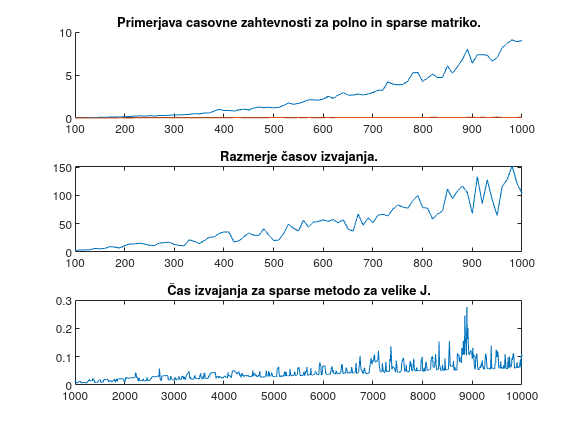

load('cas_full.mat');
load('cas_sparse.mat');
load('cas_sparse_901.mat');

clf;
tiledlayout(3,1)

nexttile
hold on;
plot(100:10:1000,cas_full);
plot(100:10:1000,cas_sparse);
title("Primerjava casovne zahtevnosti za polno in sparse matriko.")
hold off;

nexttile
plot(100:10:1000,cas_full./cas_sparse)
title("Razmerje časov izvajanja.")

nexttile 
plot(1000:10:10000,cas_sparse_901)
title("Čas izvajanja za sparse metodo za velike J.")

### Prostorska zahtevnost

Matrika, ki jo naredimo med reševanjem diferenčne metode, ima zelo malo neničelnih elementov. Natančneje, ima samo $3J -2$ neničelnih elementov.

Spodaj je naveden primer metode, ki za naš problem naredi navadno MATLAB matriko.

`x_val = linspace(a,b,J+2);`

`h = (b - a)/(J + 1);`

`c = @(x) q(x)*h^2 + (p(x+0.5*h)+(p(x-0.5*h)));`

`d = @(x) -p(x+0.5*h);`

`c_vals = arrayfun(c,x_val(2:end-1));`

`d_vals = arrayfun(d,x_val(2:end-2));`

`A = diag(c_vals) + diag(d_vals,1) + diag(d_vals,-1);`

Za primerjavo, imamo tukaj še izsek kode, ki naredi enako matriko, ampak jo zapiše kot razpršeno (sparse).

Spodaj je uporabljena metoda spdiags, ki naredi razpršeno diagonalno matriko.

`x_val = linspace(a,b,J+2);`

`h = (b - a)/(J + 1);`

`c = @(x) q(x)*h^2 + (p(x+0.5*h)+(p(x-0.5*h)));`

`d = @(x) -p(x+0.5*h);`

`c_vals = arrayfun(c,x_val(2:end-1));`

`d_vals = arrayfun(d,x_val(2:end-2));`

`M = [[d_vals,0]' c_vals' [0,d_vals]'];`

`A = spdiags(M,-1:1,J,J);`

Glavni razlog za uporabo razpršenih matrik je to da, uporabijo precej manj prostora kot navadne matrike.

Namesto, da je shranjen vsak element posebaj, je v primeru razpršenih matrik vsak neničelen element shranjen v tabelo. 

Vrstni red je določen najprej s stolpcem, v katerem je element, in potem še z vrstico.

Za vsak element si zapomnimo še vrstico, kateri je pripadal. 

Nato naredimo še tabelo, v kateri so indeksi elementov iz prvih dveh tabel, ki predstavljajo pri in zadnji element v nekem stolpcu.

Če imamo matriko z $J$ stolpci, ki vsebuje $k$ neničelnih elementov, si MATLAB zapomni $J$ realnih števil in $J + k + 1$celih števil.

x = log([1 10 100 1000 10000 100000])/log(10);
y_f = log([8 800 80000 8000000 800000000 80000000000]/8)/log(10)

y_f =                    0   2.000000000000000   4.000000000000000   5.999999999999999   8.000000000000000  10.000000000000000


y_s = log([32 536 5576 55976 559976 5599976]/8)/log(10)

y_s =    0.602059991327962   1.826074802700826   2.843232778098009   3.844911873912141   4.845079426994751   5.845096178748202


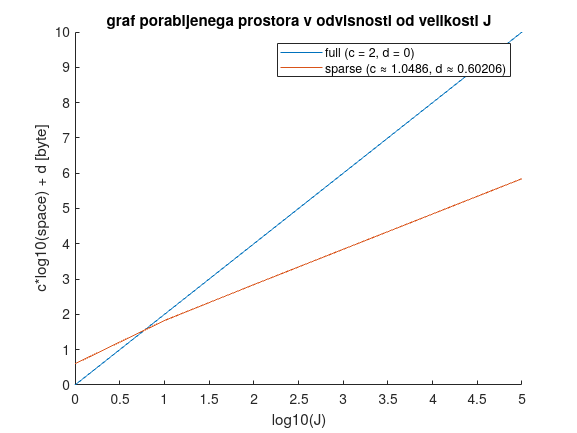

figure
hold on
xlabel('log10(J)')
ylabel('c*log10(space) + d [byte]')
plot(x,y_f);
plot(x,y_s);
title('graf porabljenega prostora v odvisnosti od velikosti J')
legend('full (c = 2, d = 0)','sparse (c ≈ 1.0486, d ≈ 0.60206)')

### Primerjava

load("PRIMER_ENA.mat")
load("PRIMER_SIN.mat")
load("PRIMER_TRI.mat")
load("PRIMER_STIRI.mat")


PRIMER_ENA

PRIMER_ENA =                    0
  -0.035516733904753
  -0.062345922648590
  -0.080489408188190
  -0.090356165039216
  -0.092669037768766
  -0.088344011444507
  -0.078372335714951
  -0.063725574048313
  -0.045291253651631


PRIMER_ENA_TEST

PRIMER_ENA_TEST =                    0
  -0.035516733904753
  -0.062345922648590
  -0.080489408188190
  -0.090356165039216
  -0.092669037768766
  -0.088344011444507
  -0.078372335714951
  -0.063725574048313
  -0.045291253651631


PRIMER_SIN

PRIMER_SIN =    1.000000000000000
   0.861163122114571
   0.441356348689379
  -0.122450839991133
  -0.646306248529709
  -0.959292665500008
  -0.959292665500005
  -0.646306248529702
  -0.122450839991125
   0.441356348689386


PRIMER_SIN_TEST

PRIMER_SIN_TEST =    1.000000000000000
   0.861163122114571
   0.441356348689379
  -0.122450839991133
  -0.646306248529709
  -0.959292665500008
  -0.959292665500005
  -0.646306248529702
  -0.122450839991125
   0.441356348689386


PRIMER_TRI

PRIMER_TRI =    6.000000000000000
  -1.143414417580916
   0.217906502216883
  -0.041564743234860
   0.008123258514834
  -0.002609670837545
   0.006068174634788
  -0.030389163126841
   0.159188596749188
  -0.835281057211717


PRIMER_TRI_TEST

PRIMER_TRI_TEST =    6.000000000000000
  -1.143414417580916
   0.217906502216883
  -0.041564743234860
   0.008123258514834
  -0.002609670837545
   0.006068174634788
  -0.030389163126841
   0.159188596749188
  -0.835281057211717


PRIMER_STIRI

PRIMER_STIRI = 1.0e+11 *

  -0.000000000120000
  -0.000002326917067
   0.000012655070830
  -0.000066474175818
   0.000349098531091
  -0.001827862959413
   0.009653031013464
  -0.049714668425007
   0.275235126654428
  -1.224701277195217


PRIMER_STIRI_TEST

PRIMER_STIRI_TEST = 1.0e+11 *

  -0.000000000120000
  -0.000002326917067
   0.000012655070830
  -0.000066474175818
   0.000349098531091
  -0.001827862959413
   0.009653031013464
  -0.049714668425007
   0.275235126654428
  -1.224701277195217
